clc
clear all
close all
s=tf('s');
W = 10.^(-4:0.01:4)';

## Questão 1

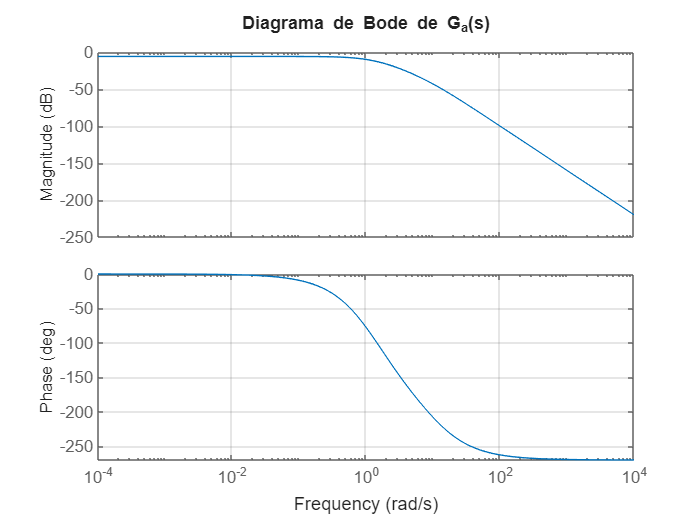

Ga = 10/((s+1)*(s+2)*(s+10));
figure
bode(Ga,W)
grid on
title('Diagrama de Bode de G_a(s)')

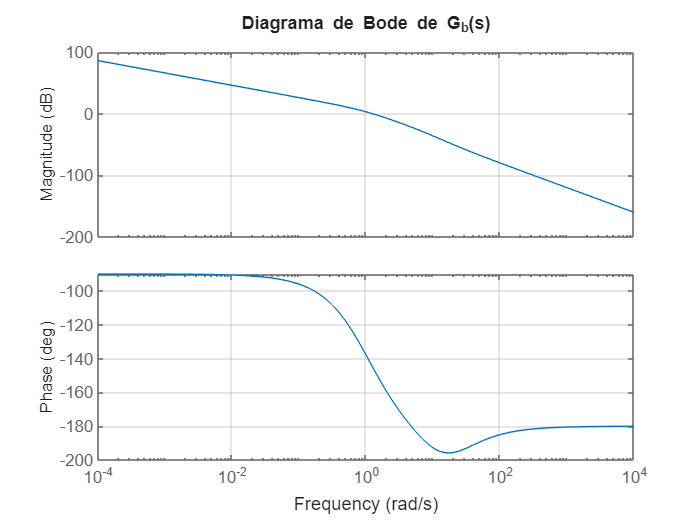

Gb = (s+20)/(s*(s+1)*(s+10));
figure
bode(Gb,W)
grid on
title('Diagrama de Bode de G_b(s)')

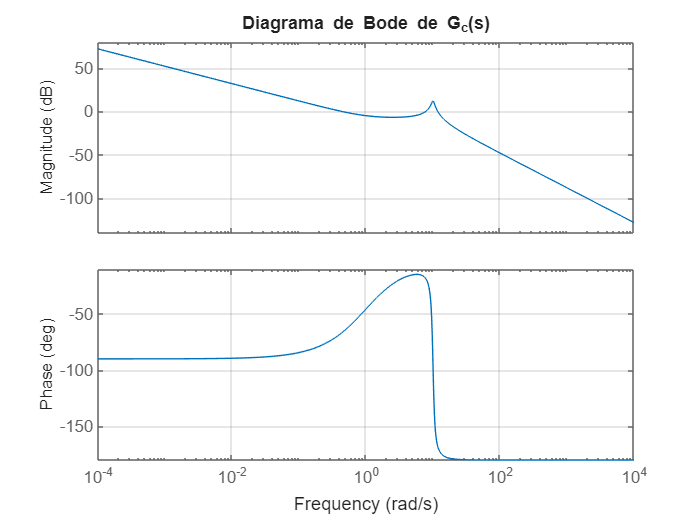

Gc = 40*(s+1)/(s*(s^2+s+100));
figure
bode(Gc,W)
grid on
title('Diagrama de Bode de G_c(s)')

## Questão 2

% Bode A
gmA = 32;
pmA = inf;
Tma = inf;
KcrA = 10^(gmA/20)

KcrA = 39.8107

% Bode B
gmB = 21.7;
pmB = 35.2;
w0db = 1.25;
TmB = (pmB*pi)/(w0db*180)

TmB = 0.4915

KcrB = 10^(gmB/20)

KcrB = 12.1619

% Bode C
gmC = inf;
pmC = 12.2;
w0db = 11.18;
TmC = (pmC*pi)/(w0db*180)

TmC = 0.0190

KcrC = 10^(gmC/20)

KcrC = Inf

## Questão 3

% Bode A
Kp = 10^(-6.02/20)

Kp = 0.5000

ep = 1/(1+Kp)

ep = 0.6667

Kv = 0;
ev = 1/Kv

ev = Inf

% Bode B
Kp = inf;
ep = 1/(1+Kp)

ep = 0

Kv = 2;
ev = 1/Kv

ev = 0.5000

% Bode C
Kp = inf;
ep = 1/(1+Kp)

ep = 0

Kv = 0.4;
ev = 1/Kv

ev = 2.5000

## Questão 4

% Método do Ganho Crítico
% Bode A
gmA = 32;
Kcr = 10^(gmA/20)

Kcr = 39.8107

w180 = 5.66;
Pcr = (2*pi)/w180

Pcr = 1.1101

K = 0.6*Kcr

K = 23.8864

Ti = Pcr/2

Ti = 0.5551

Td = Pcr/8

Td = 0.1388

Kp = K

Kp = 23.8864

Ki = K/Ti

Ki = 43.0346

Kd = K*Td

Kd = 3.3146

C = Kp + Ki/s + Kd*s


C =
 
  3.315 s^2 + 23.89 s + 43.03
  ---------------------------
               s
 
Continuous-time transfer function.
Model Properties


% Método do Ganho Crítico
% Bode B
gmB = 21.7;
Kcr = 10^(gmB/20)

Kcr = 12.1619

w180 = 4.71;
Pcr = (2*pi)/w180

Pcr = 1.3340

K = 0.6*Kcr

K = 7.2971

Ti = Pcr/2

Ti = 0.6670

Td = Pcr/8

Td = 0.1668

Kp = K

Kp = 7.2971

Ki = K/Ti

Ki = 10.9401

Kd = K*Td

Kd = 1.2168

C = Kp + Ki/s + Kd*s


C =
 
  1.217 s^2 + 7.297 s + 10.94
  ---------------------------
               s
 
Continuous-time transfer function.
Model Properties


## Questão 5

% Para o Bode A, 50 =< pm <= 60 e ep =< 1%
Kp_alvo = 99

Kp_alvo = 99

K0 = 10^(16.2/20)

K0 = 6.4565

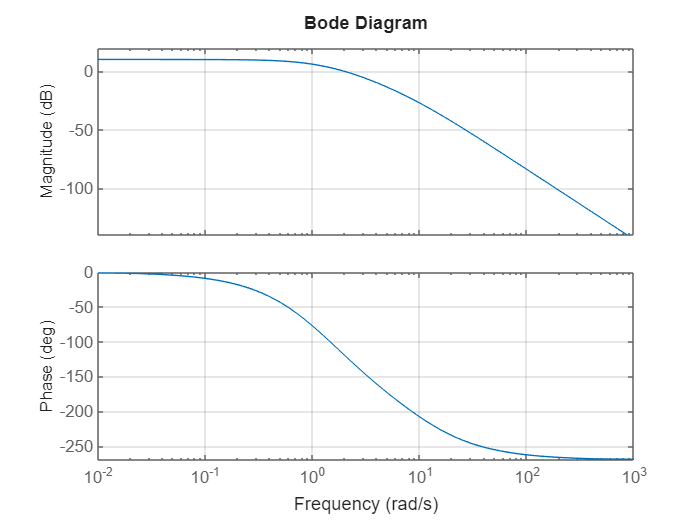

bode(K0*Ga)
grid on

w0db_novo = 2;
Kp_novo = 10^(10.2/20)

Kp_novo = 3.2359

alpha = Kp_alvo/Kp_novo

alpha = 30.5939

za = w0db_novo/10

za = 0.2000

pa = za/alpha

pa = 0.0065

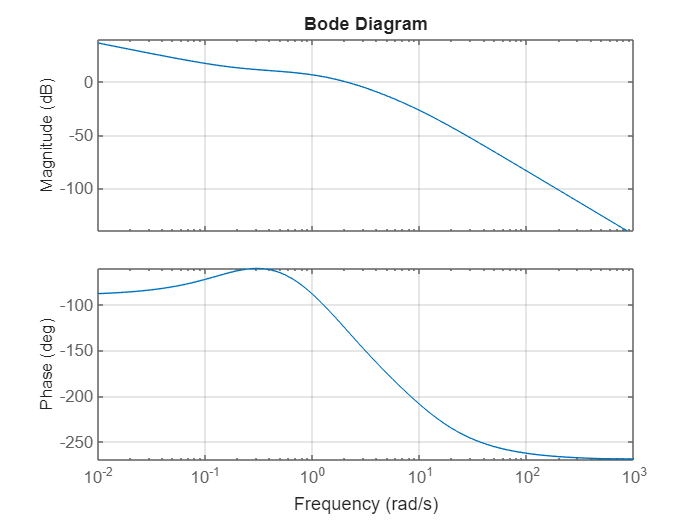

Ca = K0*((s+za)/s+pa);
bode(Ca*Ga)
grid on

## Questão 6

% Para o Bode B Margem de fase entre 40 e 50 graus Frequência de cruzamento 0 dB entre 9 e 11 rad/s.
w0db_desejado = 10;
M = -36.1; % magnitude em 10 rad/s
K0 = 10^((-M)/20)

K0 = 63.8263

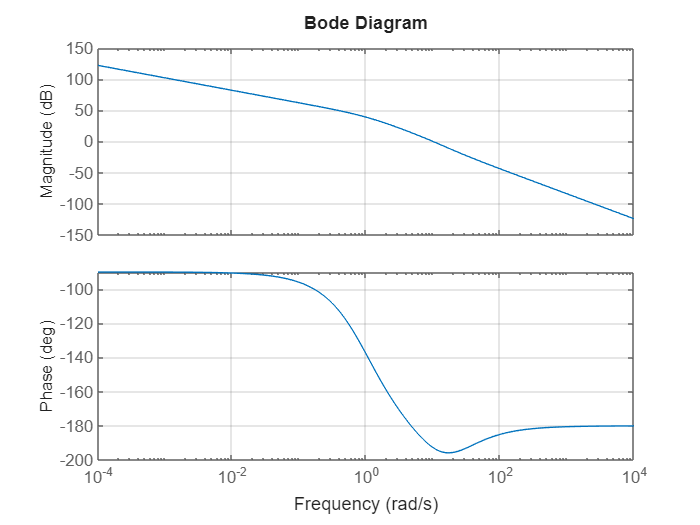

bode(K0*Gb,W)
grid on

Pm_alvo = 45;
Pm_atual = -12.7;
thetaM = Pm_alvo - Pm_atual

thetaM = 57.7000

beta = ((1+sind(thetaM))/(1-sind(thetaM)))

beta = 11.9251

pb = w0db_desejado*sqrt(beta)

pb = 34.5327

zb = pb/beta

zb = 2.8958

Kb = sqrt(beta)

Kb = 3.4533

Cb = K0*(Kb*(s+zb)/(s+pb))


Cb =
 
  220.4 s + 638.3
  ---------------
     s + 34.53
 
Continuous-time transfer function.
Model Properties


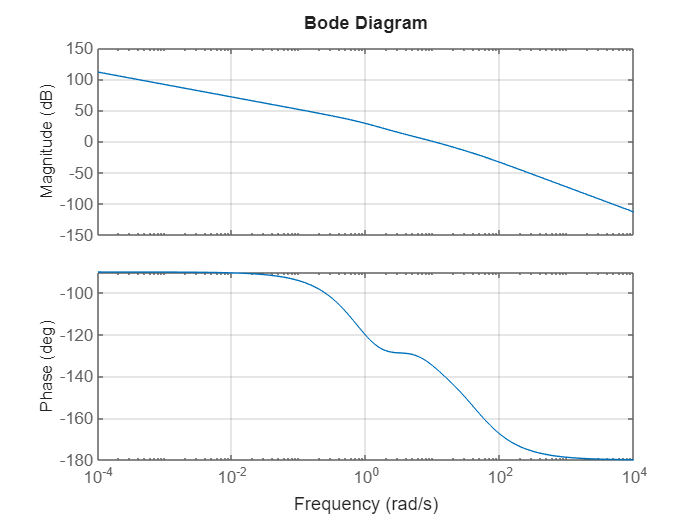

bode(Cb*Gb,W)
grid on

## Questão 7

% Margem de fase entre 60 e 70 graus;
% Frequência de cruzamento 0 dB entre 25 e 35 rad/s;
% Erro em regime permanente de velocidade entre um centésimo e um milésimo.

M = -26.2; % magnitude em 30 rad/s
K0 = 10^((-M)/20)

K0 = 20.4174

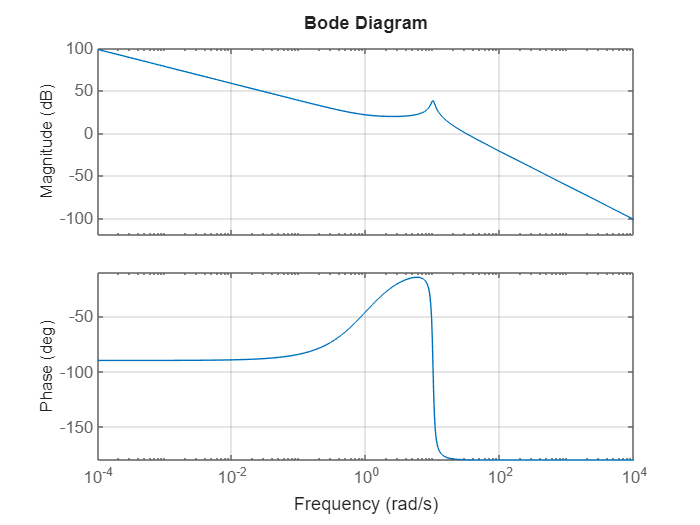

bode(K0*Gc,W)
grid on

% Pm_alvo = 65 + 5 = 70°
Pm = 0.231;
thetaM = 70 - Pm

thetaM = 69.7690

beta = ((1+sind(thetaM))/(1-sind(thetaM)))

beta = 31.4181

pb = 30*sqrt(beta)

pb = 168.1555

zb = pb/beta

zb = 5.3522

Kb = sqrt(beta)

Kb = 5.6052

Cb = K0*(Kb*(s+zb)/(s+pb))


Cb =
 
  114.4 s + 612.5
  ---------------
     s + 168.2
 
Continuous-time transfer function.
Model Properties


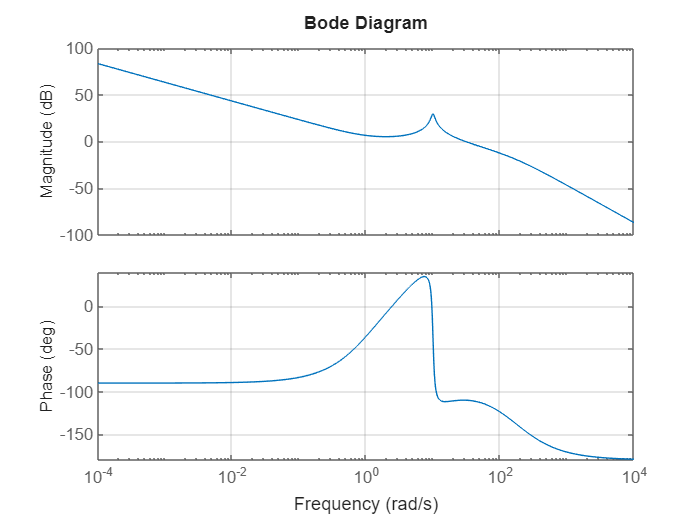

bode(Cb*Gc,W)
grid on

% 100 =< kv =< 1000
kv_alvo = 500;
kv_atual = 10; % Pelo Bode
alpha = kv_alvo / kv_atual

alpha = 50

w0db_atual = 30;
za = w0db_atual/10

za = 3

pa = za/alpha

pa = 0.0600

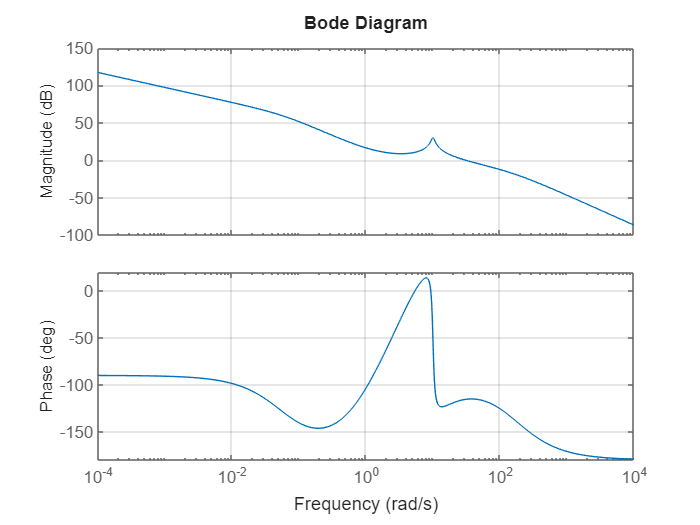

Cs = K0 * ((s+za)/(s+pa)) * (Kb*(s+zb)/(s+pb));
bode(Cs*Gc, W)
grid on